% model-free RL with continuous action space - make sure to set the agent
% in the RL Agent block to agentModelFreeRL

%% PENDULUM PARAMETERS %%
init_angle=180   % Initial angle from vertical (degrees)

init_angle = 180

n_links=7       % Number of links 

n_links = 7


L=60;           % Total length of pendulum (cm)
W=2;            % Width of links (cm)
H=2;            % Depth of links (cm)
damping=0.01;     % Damping factor at joints (N*m/(deg/s))

spring=0.01;    % Torsional spring constant (N*m/deg)

base_damping= 0.5; 
max_torque =  25;

%% MEASUREMENT PARAMETERS %%
coord_noise_std=0;
angle_noise_std=0;

open_system("pendulum_system_RL_model_free")

% Resetting model to default
for i=1:19
    set_param(sprintf('pendulum_system_RL_model_free/pendulum_links/pendulum_link_%d',i),'commented','off');
end

% Initialising number of links
for i=1:(20-n_links)
    set_param(sprintf('pendulum_system_RL_model_free/pendulum_links/pendulum_link_%d',i),'commented','through');
end
Ts = 0.1;
Tf = 100;
dt = Ts;

% Setting up environment

obsInfo = rlNumericSpec([10 1])

obsInfo =   rlNumericSpec with properties:

     LowerLimit: -Inf
     UpperLimit: Inf
           Name: [0×0 string]
    Description: [0×0 string]
      Dimension: [10 1]
       DataType: "double"


obsInfo.Name = "Robot States";
obsInfo.Description = "sin_phi, cos_phi, sin_theta, cos_theta, ex, ez, dphi, dx, dz, dtheta";

actInfo = rlNumericSpec(1);
actInfo.Name = "Motor Torque";
actInfo.LowerLimit = -max_torque;
actInfo.UpperLimit = max_torque;

envModelFree = rlSimulinkEnv("pendulum_system_RL_model_free", ...
    "pendulum_system_RL_model_free/RL Agent", ...
    obsInfo,actInfo);

% NEED TO CREATE A RESET FUNCTION TO RANDOMLY INITIALISE THE STARTING ANGLE
% OF THE PENDULUM

envModelFree.ResetFcn = @(in)localResetFcn(in);
Taverage = 0.75;
rng(0)

% Checking environment
getObservationInfo(envModelFree)

ans =   rlNumericSpec with properties:

     LowerLimit: -Inf
     UpperLimit: Inf
           Name: "Robot States"
    Description: "sin_phi, cos_phi, sin_theta, cos_theta, ex, ez, dphi, dx, dz, dtheta"
      Dimension: [10 1]
       DataType: "double"


getActionInfo(envModelFree)

ans =   rlNumericSpec with properties:

     LowerLimit: -25
     UpperLimit: 25
           Name: "Motor Torque"
    Description: [0×0 string]
      Dimension: [1 1]
       DataType: "double"


% Setting up critic (DDPG)
statePath = [
    featureInputLayer(obsInfo.Dimension(1),Name="netObsIn")
    fullyConnectedLayer(48)
    reluLayer
    fullyConnectedLayer(24,Name="CriticStateFC2")];

actionPath = [
    featureInputLayer(actInfo.Dimension(1),Name="netActIn")
    fullyConnectedLayer(24,Name="CriticActionFC1")];

commonPath = [
    additionLayer(2,Name="add")
    reluLayer
    fullyConnectedLayer(1,Name="CriticOutput")];

criticNetwork = layerGraph();
criticNetwork = addLayers(criticNetwork,statePath);
criticNetwork = addLayers(criticNetwork,actionPath);
criticNetwork = addLayers(criticNetwork,commonPath);

criticNetwork = connectLayers(criticNetwork, ...
    "CriticStateFC2", ...
    "add/in1");
criticNetwork = connectLayers(criticNetwork, ...
    "CriticActionFC1", ...
    "add/in2");

criticNetwork = dlnetwork(criticNetwork);
summary(criticNetwork)

   Initialized: true

   Number of learnables: 1.7k

   Inputs:
      1   'netObsIn'   10 features
      2   'netActIn'   1 features



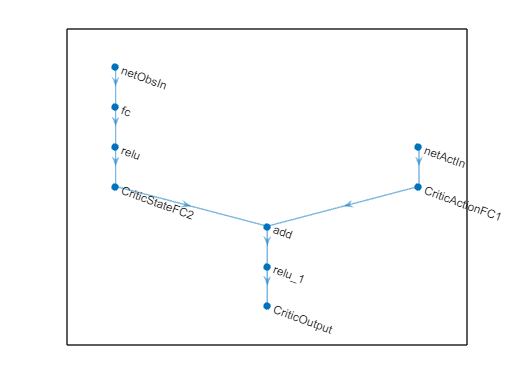

% Displaying critic
figure
plot(criticNetwork)

% Creating critic approximator
critic = rlQValueFunction(criticNetwork,obsInfo,actInfo, ...
    ObservationInputNames="netObsIn", ...
    ActionInputNames="netActIn");

getValue(critic, ...
    {rand(obsInfo.Dimension)}, ...
    {rand(actInfo.Dimension)})

ans = single
0.0180

% Creating the actor
actorNetwork = [
    featureInputLayer(obsInfo.Dimension(1))
    fullyConnectedLayer(3)
    tanhLayer
    fullyConnectedLayer(actInfo.Dimension(1))
    ];
actorNetwork = dlnetwork(actorNetwork);
summary(actorNetwork)

   Initialized: true

   Number of learnables: 37

   Inputs:
      1   'input'   10 features



actor = rlContinuousDeterministicActor(actorNetwork,obsInfo,actInfo);

getAction(actor,{rand(obsInfo.Dimension)})

ans = 1×1 cell array
    {[-0.4787]}


% Creating the agent

agentModelFreeRL = rlDDPGAgent(actor,critic);
agentModelFreeRL.SampleTime = Ts;

agentModelFreeRL.AgentOptions.TargetSmoothFactor = 1e-3;
agentModelFreeRL.AgentOptions.DiscountFactor = 1.0;
agentModelFreeRL.AgentOptions.MiniBatchSize = 64;
agentModelFreeRL.AgentOptions.ExperienceBufferLength = 1e6;

agentModelFreeRL.AgentOptions.NoiseOptions.Variance = 2.5;
agentModelFreeRL.AgentOptions.NoiseOptions.VarianceDecayRate = 1e-5;

%agentModelFreeRL.AgentOptions.ExplorationModelParameters = rlExplorationModel

agentModelFreeRL.AgentOptions.CriticOptimizerOptions.LearnRate = 1e-03;
agentModelFreeRL.AgentOptions.CriticOptimizerOptions.GradientThreshold = 1;
agentModelFreeRL.AgentOptions.ActorOptimizerOptions.LearnRate = 1e-04;
agentModelFreeRL.AgentOptions.ActorOptimizerOptions.GradientThreshold = 1;
getAction(agentModelFreeRL,{rand(obsInfo.Dimension)})

ans = 1×1 cell array
    {[0.1761]}


% Training agent
global episode_number;
episode_number = 0;
trainOpts = rlTrainingOptions(...
    MaxEpisodes=5000, ...
    MaxStepsPerEpisode=ceil(Tf/Ts), ...
    ScoreAveragingWindowLength=40, ...
    Verbose=false, ...
    Plots="training-progress",...
    StopTrainingCriteria="AverageReward",...
    StopTrainingValue=120);

trainingStats = train(agentModelFreeRL,envModelFree,trainOpts);

% Simulate environment
simOpts = rlSimulationOptions(MaxSteps=ceil(100*Tf/Ts),StopOnError="off");
experiences = sim(envModelFree,agentModelFreeRL,simOpts);
